Map

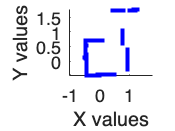

load('hw8_data.mat','angles','positions','scans');
theta = deg2rad(angles(1));
ranges = scans{1}.ranges;
thetas = scans{1}.thetasInRadians;
robot_to_global = [cos(theta) -sin(theta) positions(1,1);
                 sin(theta) cos(theta) positions(1,2);
                 0 0 1];
lidar_to_robot = [1 0 -0.08;
                  0 1 0;
                  0 0 1];
lidar_to_global = robot_to_global * lidar_to_robot;
matrix = [cos(thetas);
        sin(thetas)].*[ranges; ranges;];
homogeneous_matrix = [matrix; ones(1, size(matrix,2))];
cleaned = homogeneous_matrix(:, ranges~=0);
global_cleaned = lidar_to_global*cleaned;
figure;
title("Position " + num2str(1))
scatter(global_cleaned(1,:), global_cleaned(2,:), 'b.');
axis("equal");
xlabel("X values")
ylabel("Y values")
hold on;
scatter(global_cleaned(1,:), global_cleaned(2,:), 'b.');
xlabel("X values")
ylabel("Y values")
axis("equal");

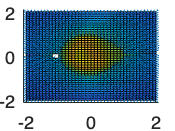

x = global_cleaned(1, :);
y = global_cleaned(2, :);
[x_grid, y_grid]=meshgrid(-2:.1:2, -2:.1:2);
f = 0; % Quiver plot equation
for i = 1:size(x,2)
    current_x = x(i);
    current_y = y(i);
    % Add all walls to the quiver plot equation so it represents the map.
    f = f - log(sqrt((x_grid-current_x).^2 + (y_grid-current_y).^2));
end

% Add the ball to the equation.
f = f + log(sqrt((x_grid + 1.1).^2 + (y_grid + 0).^2));

[fx_grid, fy_grid] = gradient(f);
% Make all vectors the same length
fx_grid = -.06 .* fx_grid ./ sqrt(fx_grid.^2 + fy_grid.^2);
fy_grid = -.06 .* fy_grid ./ sqrt(fx_grid.^2 + fy_grid.^2);
quiver(x_grid, y_grid, fx_grid, fy_grid);

surf(x_grid, y_grid, f)

Contour and gradient

V = @(x, y, a, b) -log((x - a)^2 + (y - b)^2)

V = function_handle with value:
    @(x,y,a,b)-log((x-a)^2+(y-b)^2)


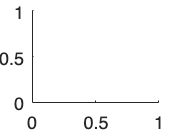


a_values = global_cleaned(1, :);
b_values = global_cleaned(2, :);

[x, y] = meshgrid(-1:0.1:10.5, -1:0.1:8);

figure();
hold on;


for i = size(global_cleaned, 2)
    contour(x, y, V(x, y, a_values(1, i), b_values(1, i)), 'LineWidth', 1.5);
end

Error using  ^ 
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To operate on each element of the matrix individually, use POWER (.^) for elementwise power.

Error in testing>@(x,y,a,b)-log((x-a)^2+(y-b)^2) (line 28)
V = @(x, y, a, b) -log((x - a)^2 + (y - b)^2)